data = importdata('ROC_REAL_50.mat');

**1.a)** Selecionamos da base de dados 10 pacientes:

% Definimos uma seed estatica para o gerador de números aleatórios de forma
% a podermos repetir os experimentos com os mesmos resultados
rng(42);
rndIDX = randperm(50);
sample = data(rndIDX(1:10), :)

sample =     0.0219    1.2746
    0.0528    2.5362
    0.0352    1.5503
    0.0293    1.4728
    0.0308    1.9499
    0.0330    2.4823
    0.0282    1.2615
    0.0295    1.2390
    0.0329    2.5669
    0.0394    2.0425


**1.b)**

Representação de $c_e \left(t\right)$

figure(1);
%hold on
Ce = [];
for row = 1 : length(sample)
    a = sample(row,1);
    s = tf('s');
    G = (40*a^3)/((s+a)*(s+4*a)*(s+10*a));
    % Plot
    [y,t] = impulse(G * 0.6);
   % plot(t,y)
    % Save the data
    Ce = [Ce, [y, t]];
end
%hold off
Ce = Ce(2:end,:);

Representação de $r\left(t\right)$

r0 = 1;
EC50 = 1;
figure(2);
hold on
for row = 1 : length(sample)
    gamma = sample(row,2);
    Ce(:, row)
    R = r0 ./ (1 + (Ce(:, row) / EC50) * gamma);
    plot(R);
end

ans =     0.0000
    0.0001
    0.0002
    0.0003
    0.0004
    0.0006
    0.0008
    0.0010
    0.0012
    0.0014


ans =     0.4201
    0.8401
    1.2602
    1.6803
    2.1003
    2.5204
    2.9404
    3.3605
    3.7806
    4.2006


ans =     0.0001
    0.0002
    0.0004
    0.0007
    0.0011
    0.0015
    0.0019
    0.0024
    0.0029
    0.0034


ans =     0.1745
    0.3490
    0.5235
    0.6980
    0.8725
    1.0470
    1.2215
    1.3960
    1.5705
    1.7450


ans =     0.0000
    0.0001
    0.0003
    0.0005
    0.0007
    0.0010
    0.0013
    0.0016
    0.0019
    0.0023


ans =     0.2613
    0.5226
    0.7839
    1.0452
    1.3065
    1.5678
    1.8290
    2.0903
    2.3516
    2.6129


ans =     0.0000
    0.0001
    0.0002
    0.0004
    0.0006
    0.0008
    0.0011
    0.0013
    0.0016
    0.0019


ans =     0.3149
    0.6297
    0.9446
    1.2595
    1.5744
    1.8892
    2.2041
    2.5190
    2.8338
    3.1487


ans =     0.0000
    0.0001
    0.0002
    0.0004
    0.0006
    0.0009
    0.0011
    0.0014
    0.0017
    0.0020


ans =     0.2991
    0.5981
    0.8972
    1.1962
    1.4953
    1.7944
    2.0934
    2.3925
    2.6916
    2.9906


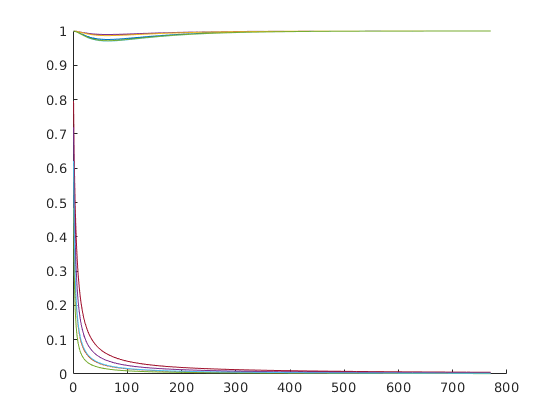

hold off